# Lab2 

Ashkan Jafari

810197483

## 1.

### 1.1

#### A)

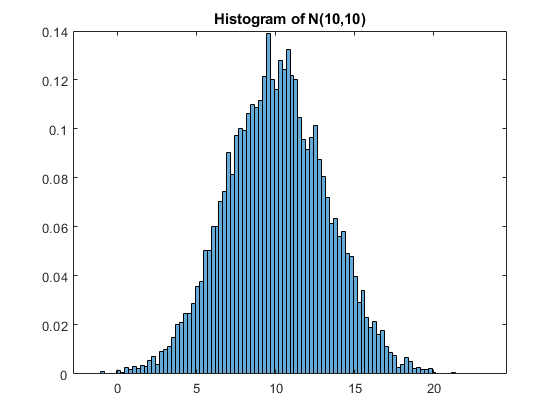

n_bin = 100;
N = 10000;
mean = 10;
variance = 10;
x1 = sqrt(variance) * randn(1,N) + mean;
histogram(x1,n_bin,"Normalization",'pdf');
title 'Histogram of N(10,10)'

#### B)

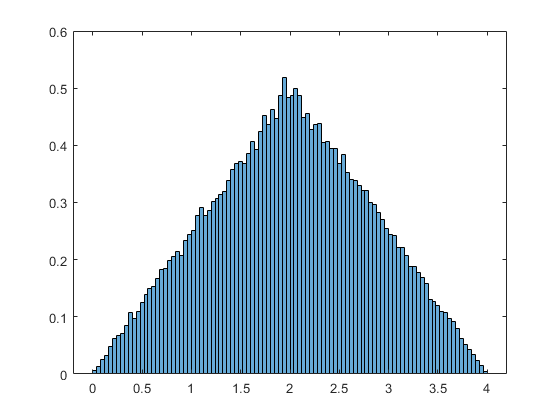

N = 100000;
x2 = rand(1,N+1) * 2;
x3 = x2(2:end) + x2(1:end-1);
histogram(x3,n_bin,"Normalization",'pdf');

If we want to know PDF of the summation of two uniform distributions, we should convolve the two PDFs.

we know that convolution of two step function will produce triangle function.

#### C.

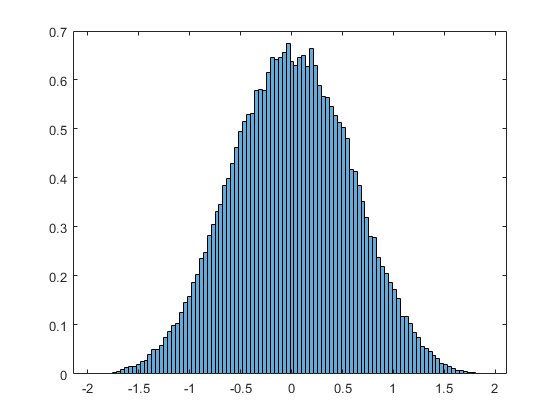

x4 =zeros(1,N);
for i=1:4
    x4 = x4 + (rand(1,N) - 0.5);
end
histogram(x4,n_bin,"Normalization",'pdf')

Just like previous part, convolution of four step function or convolution of two triangle function results this shape.

Based on "CLT", If we sum up a lot of uniform distribution, it will become a normal distribution.

## 2.

### 1

#### A)

N = 101;
n = 0:N;
x = zeros(N+4,1);
x(4) = 1;
y1 = zeros(N+4,1);
for n = 4:N
   y1(n) = 0.5 * y1(n - 1) - 0.25 * y1(n - 2) + x(n) + 2 * x(n - 1) + x(n - 3);
end
a = [1 -0.5 0.25];
b = [1 2 0 1];
y2 = filter(b,a,x)
y1 

As the above results, we could observe the non-filter using algorithm is correct!

stem(y1)

### 2

load('PacketsAndHeader.mat');
r = corr_m(hdr_smpl,rx_smpl);

y2 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


fs = 10e6;

y1 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


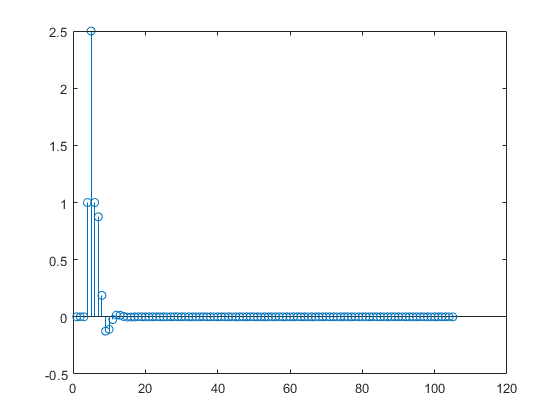

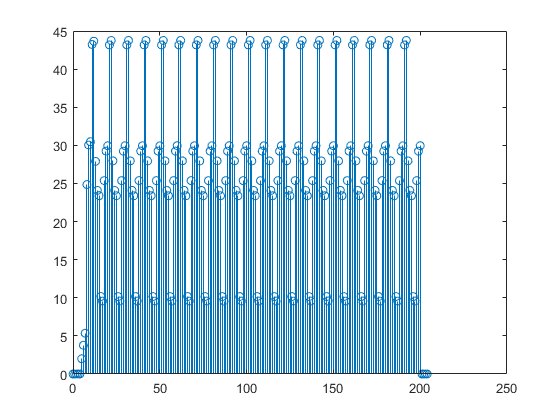

t_header = 0:1/fs:(length(hdr_smpl)-1)/fs;
plot(t_header,real(hdr_smpl),t_header,imag(hdr_smpl));

title('Header')
xlabel('n')
ylabel('y[n]')
t_rx = 0:1/fs:(length(rx_smpl)-1)/fs;
plot(t_rx,abs(rx_smpl))
title('rx_smpl')
xlabel('n')
ylabel('y[n]')

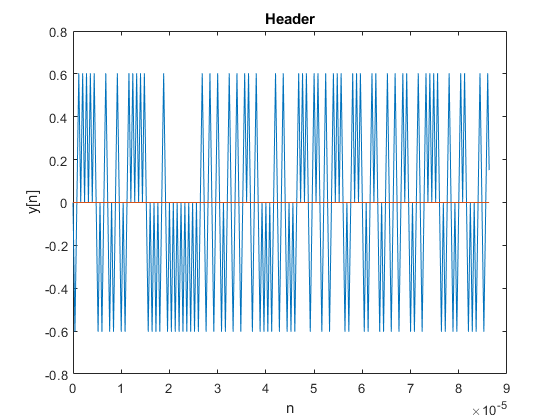

t_r = 0:1/fs:(length(r)-1)/fs;
plot(t_r,abs(r))
title('header and Packets')

ylabel('y[n]')

Delay ~= 1e-5 s

distance = c * D = 300km

### 3

**Spectral Leakage:**

Any other type of operation creates new frequency components that may be referred to as **spectral leakage** in the broadest sense. Sampling, for instance, produces leakage, which we call aliases of the original spectral component. For Fourier transform purposes, sampling is modeled as a product between s(t) and a Dirac comb function. The spectrum of a product is the convolution between S(f) and another function, which inevitably creates the new frequency components. But the term 'leakage' usually refers to the effect of *windowing*, which is the product of s(t) with a different kind of function, the window function. Window functions happen to have finite duration, but that is not necessary to create leakage. Multiplication by a time-variant function is sufficient.

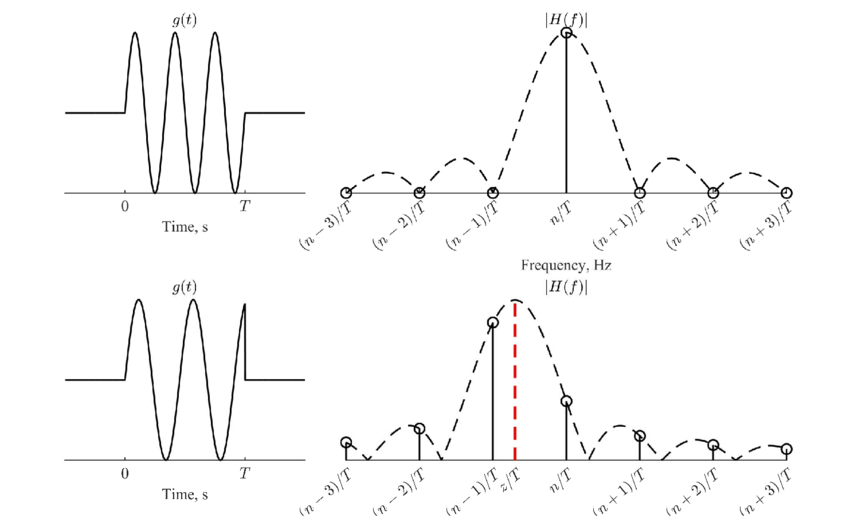

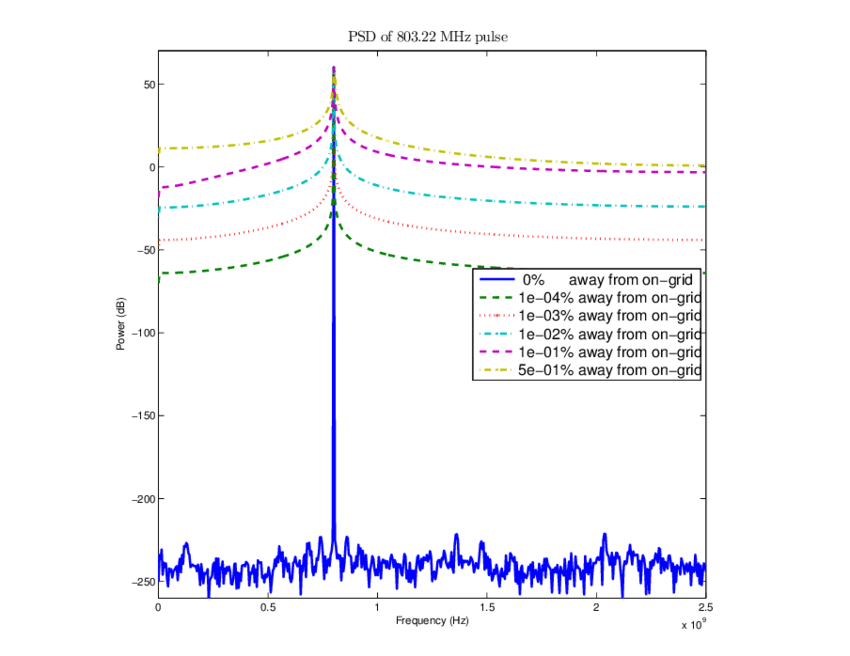

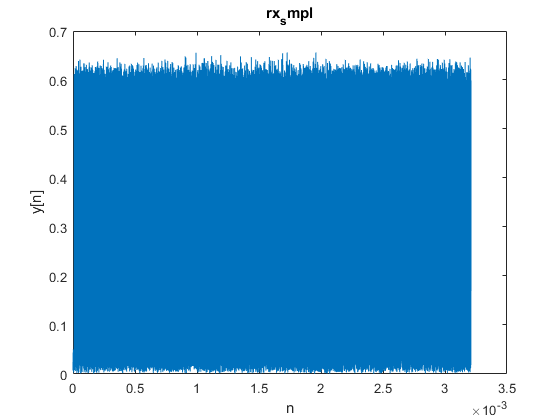

A = 2
f0 = (250 * 51 / 256) * 1e6 
n_fft = 256
fs = 250e6;

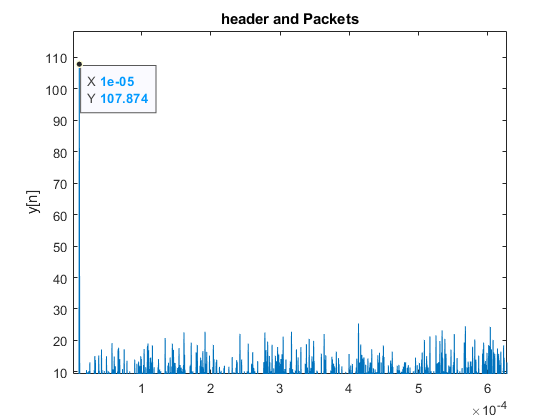

ts = 1/fs;
freq_resolution = fs/n_fft
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1j*2*pi*t*f0*ts);


Xf = fftshift(fft(x, n_fft)); %not normalized
Xf = fftshift(fft(x, n_fft))/n_fft;

stem(freq, abs(Xf).^2);
xlim([-125e6,125e6]);
ratio = n_fft * ts * f0
power_time = sum(abs(x).^2)/length(x)
power_freq = sum(abs(Xf).^2)

A = 2

R = 50

f0 = 4.9805e+07

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

n_fft = 256

A = 2
f0 = (250 * 51.5 / 256 ) * 1e6
n_fft = 256

freq_resolution = 9.7656e+05

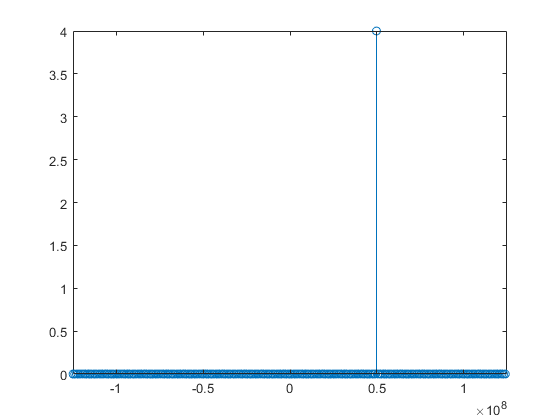

ratio = 51

fs = 250e6;
freq_resolution = fs/n_fft
ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

power_time = 4

power_freq = 4

power_time = sum(abs(x).^2)/length(x)

R = 50

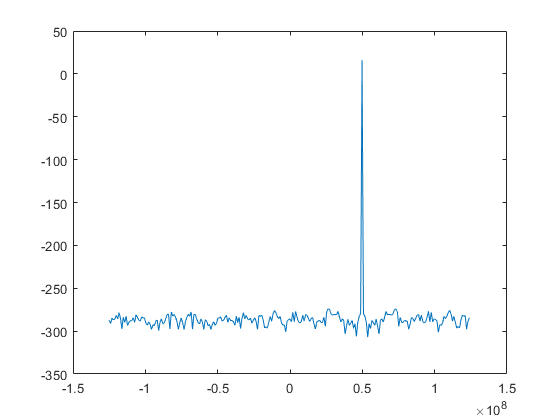

power_freq = sum(abs(Xf).^2)

R = 50;
plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

A = 2

A = 2

f0 = 5.0293e+07

f0 = (250 * 51 / 256) * 1e6 

n_fft = 256

n_fft = 512
fs = 250e6;

freq_resolution = 9.7656e+05

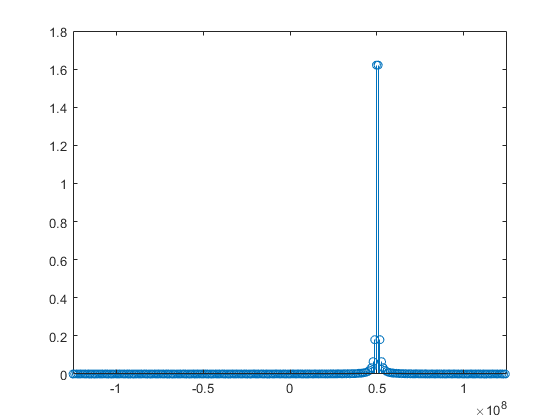

freq_resolution = fs/n_fft
ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)

xlim([-125e6,125e6])
ratio = n_fft * ts * f0

ratio = 51.5000

time_power = sum(abs(x).^2)/length(x)
freq_power = sum(abs(Xf).^2)

power_time = 4

R = 50

power_freq = 4.0000

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

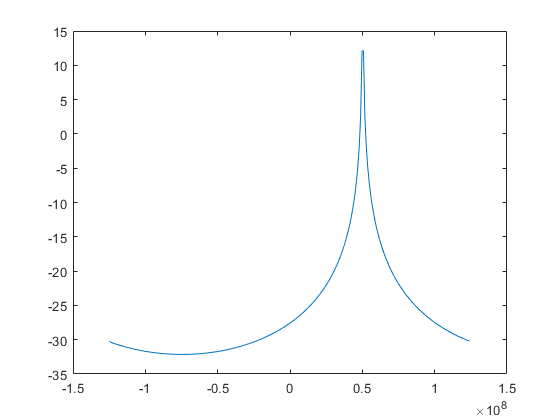

A = 2

f0 = -(250 * 51 / 256 ) * 1e6 
n_fft = 512

A = 2

fs = 250e6;

f0 = 4.9805e+07

freq_resolution = fs/n_fft

n_fft = 512

ts = 1/fs;
t = (0:n_fft-1);

freq_resolution = 4.8828e+05

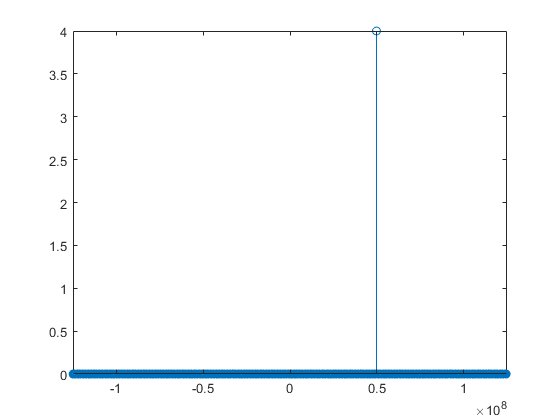

freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft)); %not normalized
Xf = fftshift(fft(x, n_fft)) /n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])
ratio = n_fft * ts * f0

time_power = sum(abs(x).^2)/length(x)

ratio = 102

freq_power = sum(abs(Xf).^2)

time_power = 4

R = 50

freq_power = 4

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

R = 50

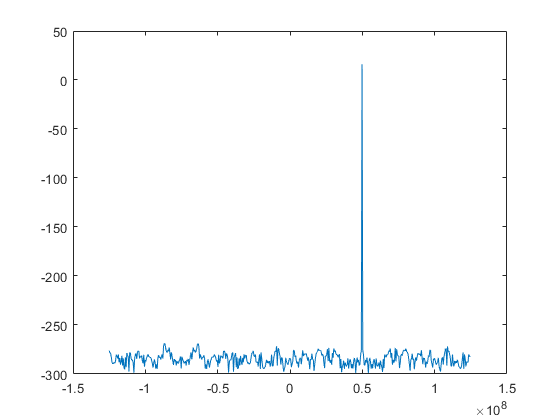

A = 4

f0 = (250 * 153 / 256 ) * 1e6 
n_fft = 512

A = 2

fs = 250e6;

f0 = -4.9805e+07

freq_resolution = fs/n_fft

n_fft = 512

ts = 1/fs;
t = (0:n_fft-1);

freq_resolution = 4.8828e+05

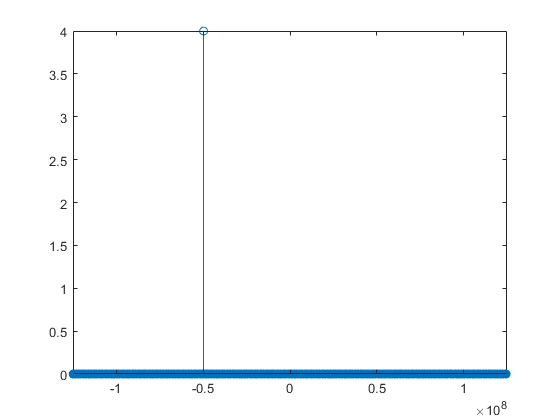

freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])
ratio = n_fft * ts * f0
time_power = sum(abs(x).^2)/length(x)
freq_power = sum(abs(Xf).^2)

R = 50

ratio = -102

Whenever the Frequency is higher than sampling frequency the below spectrum will be resulted.

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

time_power = 4

By increasing n_fft we will have better (not higher) frequency resolution. (frequency resolution = fs/n_fft)

A = 2

freq_power = 4

f0 = (250 * 51.5 / 256 ) * 1e6 

R = 50

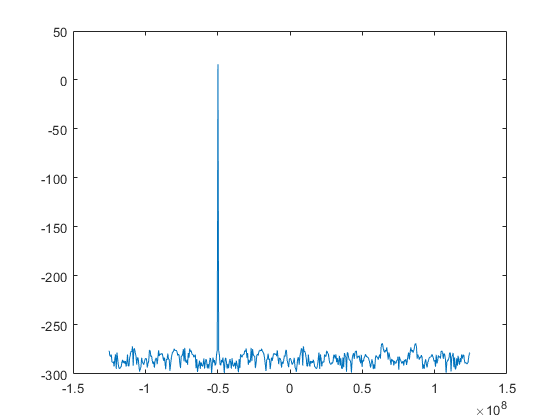

n_fft = 256

fs = 250e6;
freq_resolution = fs/n_fft

A = 4

ts = 1/fs;

f0 = 1.4941e+08

t = (0:n_fft-1);

n_fft = 512

freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);

freq_resolution = 4.8828e+05

Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

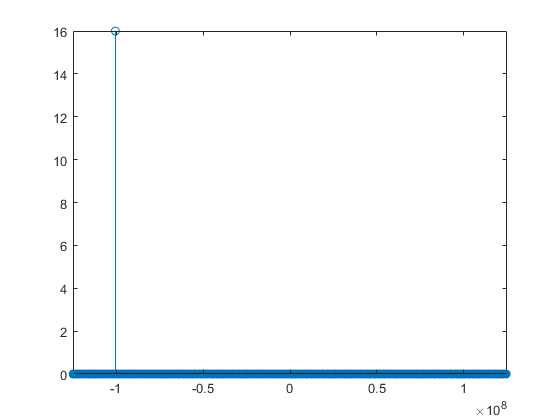

A = 2
f0 = (250 * 51.5 / 256 ) * 1e6 
n_fft = 512
fs = 250e6;

freq_resolution = fs/n_fft

ratio = 306

ts = 1/fs;

time_power = 16

t = (0:n_fft-1);

freq_power = 16

freq = (0:n_fft-1)/n_fft * fs - fs/2;

R = 50

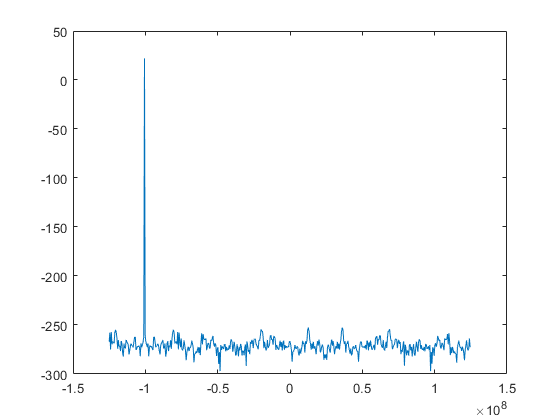

x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;

stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

A = 2

A = 2

f0 = (250 * 51.25 / 256 ) * 1e6 

f0 = 5.0293e+07

n_fft = 512

n_fft = 256

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 9.7656e+05

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

### Functions

function r = corr_m(x, y)

A = 2

r = zeros(1, abs(length(y) - length(x)) + 1);

f0 = 5.0293e+07

for i=1:length(r)

n_fft = 512

    r(i) = sum(x.*conj(y(i:i+length(x)-1)));
end

freq_resolution = 4.8828e+05

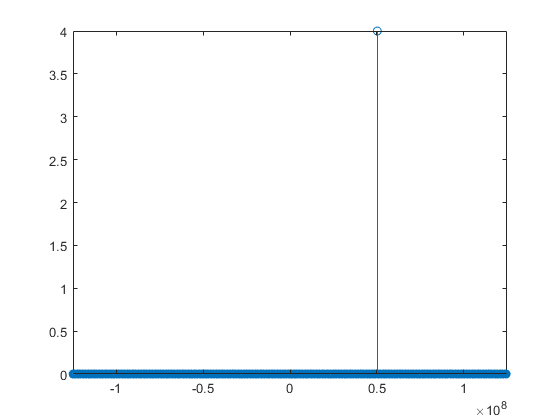

A = 2

f0 = 5.0049e+07

n_fft = 512

freq_resolution = 4.8828e+05

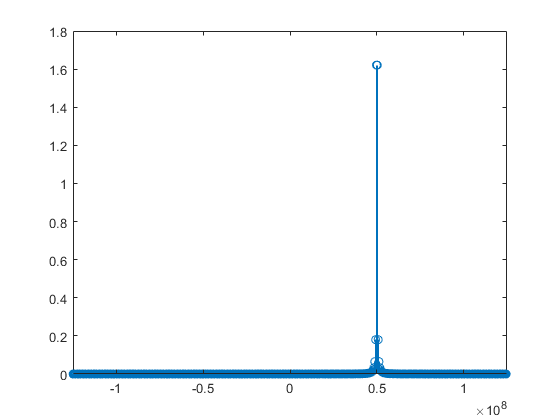

end